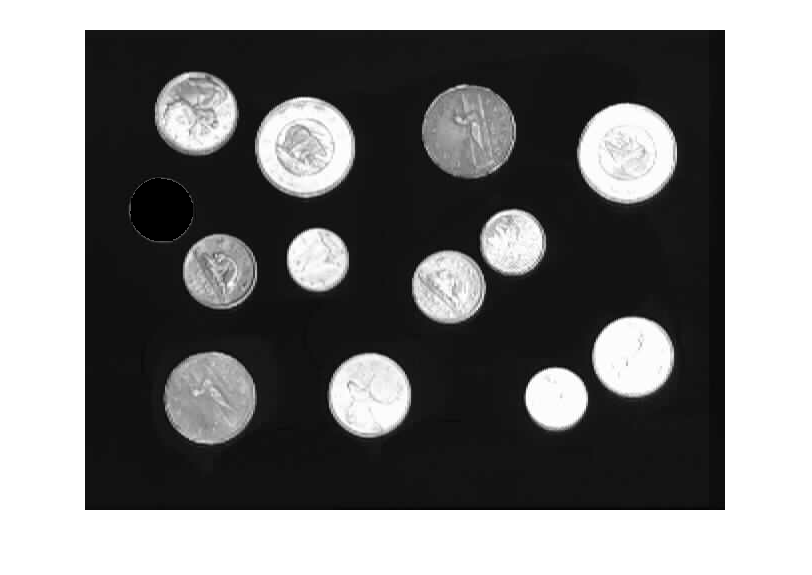

I = imread('money.tif');
BW = im2bw(I, 95/255);
C = bwconncomp(BW);
J = I;
J(C.PixelIdxList{1}) = 0;
imshow(J);

Amb el parametre C, s'han etiquetat tots els objectes que s'han detectat a la imatge.

numel(C.PixelIdxList{1});
np = cellfun(@numel, C.PixelIdxList);

Valor de np serà un vector amb l'area de totes les monedes.

[v, index] = max(np);

Amb aixo tindrem el maxim valor de np i on es troba.

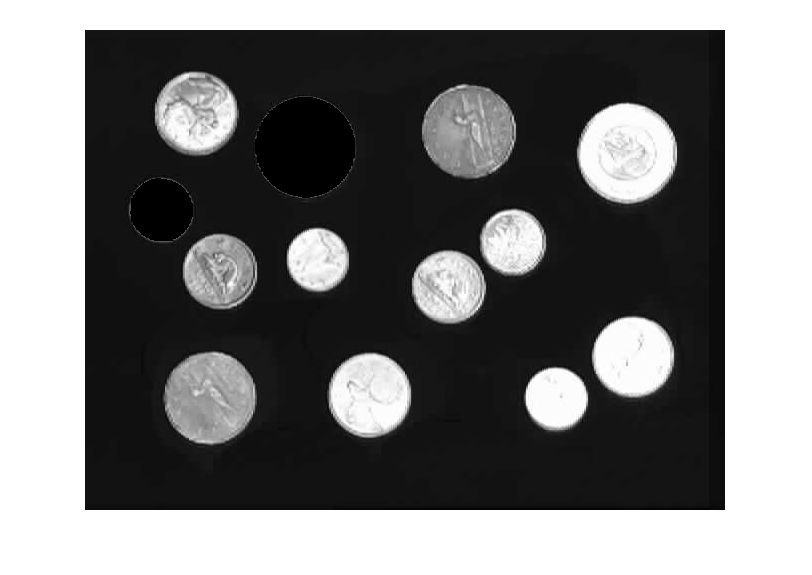

J(C.PixelIdxList{index}) = 0;
imshow(J);

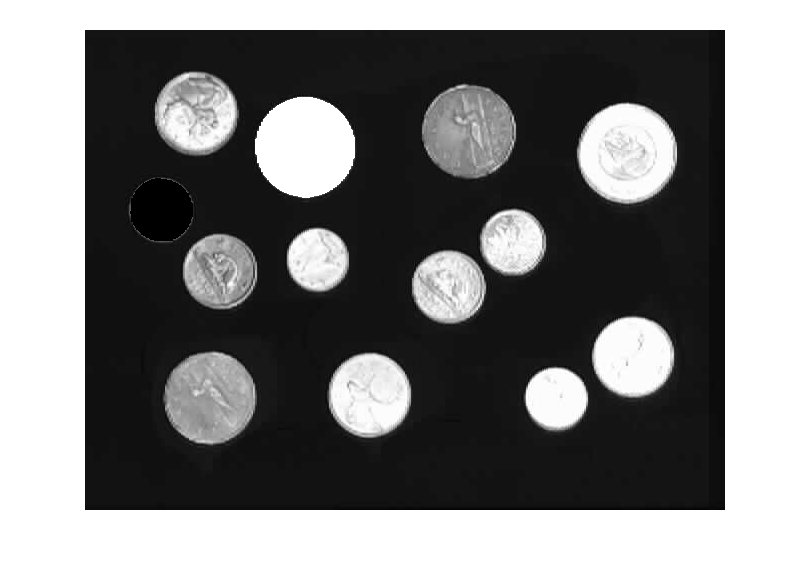

J(C.PixelIdxList{index}) = 255;
imshow(J);

Pintara primer de negre i despres de blanc la moneda mes gran.

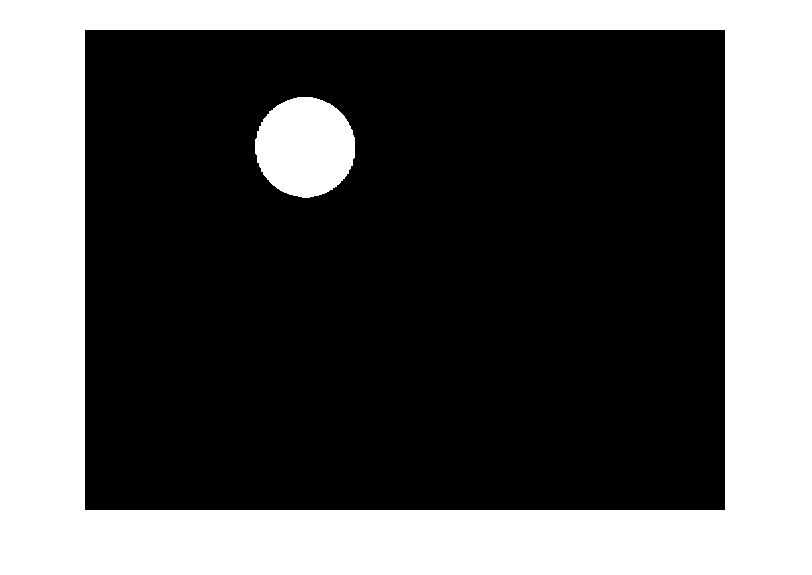

B = zeros(size(I));
B(C.PixelIdxList{index}) = 1;
imshow(B,[]);

Pintara tota la imatge de negre excepte la moneda més gran que la pintarà de blanc.

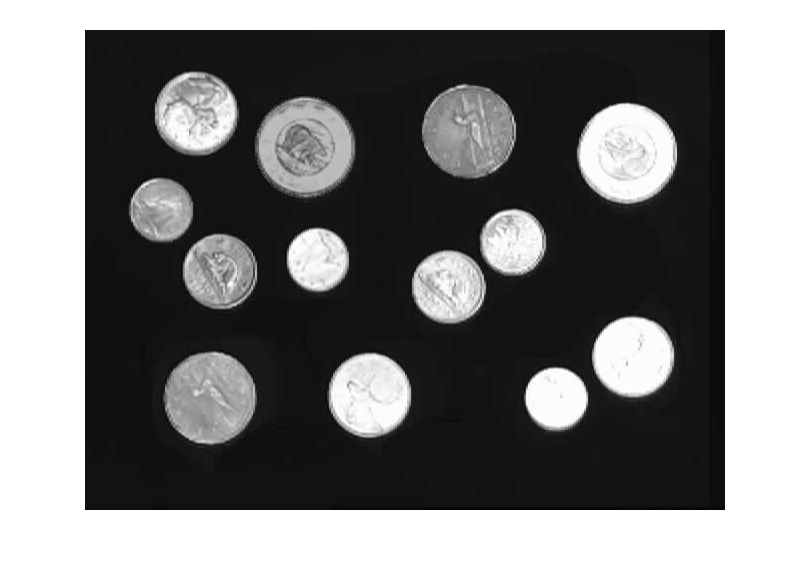

X = I - 64 * uint8(B);
imshow(X, []);

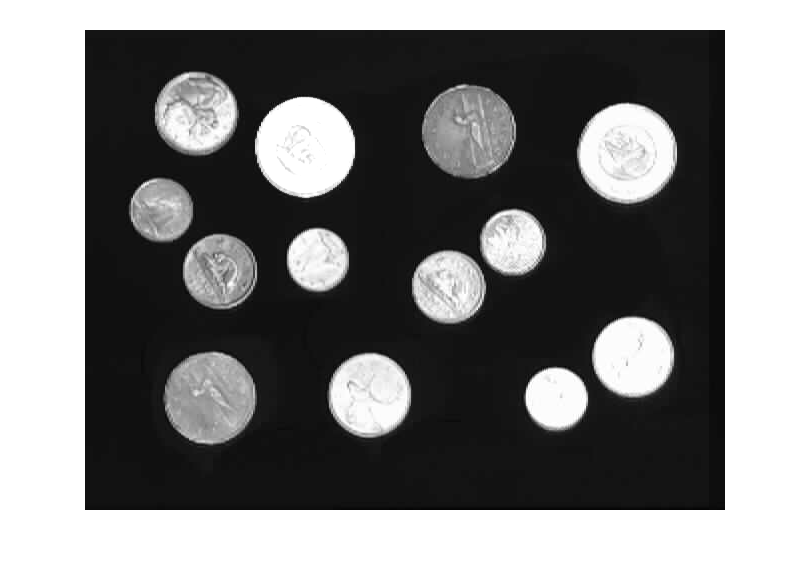

X2 = I + 64 * uint8(B);
imshow(X2, []);

Aquestes dues operacions faran més fosca i mes clara la imatge respectivament.

S = regionprops(C, 'centroid');
S = regionprops(C, 'centroid', 'BoundingBox');

Analitza els objectes segons els parametres entrats.

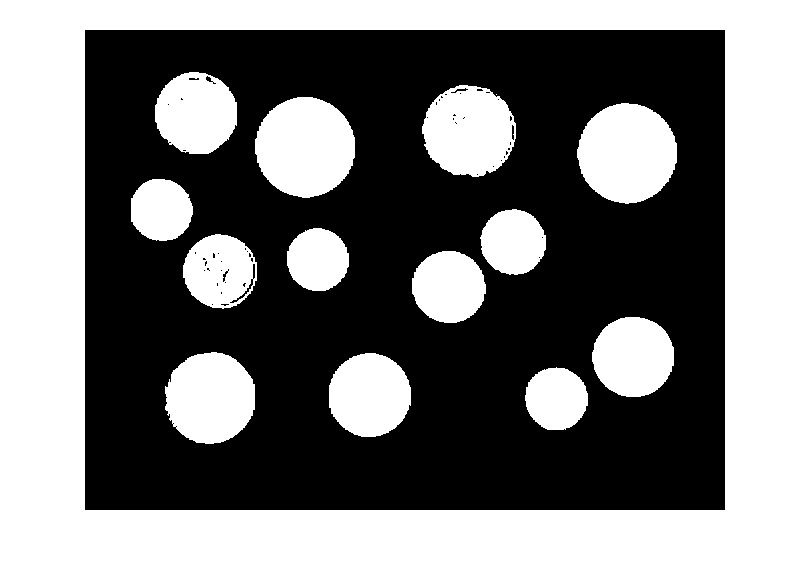

K = kmeans(double(X2(:)), 2);
Ic = reshape(K, size(X2));
imshow(Ic, []);

Fa que tots els elements de la imatge siguin blanques, son tots els elements que estan etiquetats.

Codi per probar la funció de la entrega:

I = imread('cat.jpg');
Indg = rgb2gray(I);
imshow(Indg);
rect = getrect;
rectIm = imcrop(Indg, rect);
hp = imhist(rectIm);
hg = imhist(Indg);
hg2 = hg - hp;